# Dominant Spectral Zero Method (DSZM)

## Introduction

DSZM from Ionutiu et al. [1] is a passivity-preserving reduction method that builds on an earlier result from Antoulas [2]. To preserve passivity the method interpolates the FOM at a set of spectral zeros. The approach utilizes the dominant pole algorithms presented in [4,5] to compute the most dominant spectral zeros according to a dominance criterion. Interpolation at these dominant spectral zeros is assumed to provide better approximation results.

## **Idea**

First an associated Hamiltonian system $\Sigma_h$ is computed with system matrices $A_h =   \pmatrix{A-B\Delta C & -B \Delta B^\mathrm{T}  \cr C^\mathrm{T} \Delta C  & -A^\mathrm{T} + C^\mathrm{T} \Delta B^\mathrm{T} }$, $E_h =   \pmatrix{E & 0 \cr 0 & E^\mathrm{T}}$, $B_h = \pmatrix{B \cr C^\mathrm{T}} \Delta$, $C_h = -\Delta \pmatrix{C & B^\mathrm{T}}$, $\Delta = (D+D^\mathrm{T})^{-1}$. Then the *r* most dominant spectral zeros are computed as the dominant poles of $\Sigma_h$ with sadpa/samdp [4,5]. Next, we compute the projection matrices $V,W$ as the rational Krylov subspaces


$$V = [(s_1E-A)^{-1}B,\ldots,(s_rE-A)^{-1}B]$$


$W = [(-s_1^*E^*-A^*)^{-1}C^*,\ldots,(-s_r^*E^*-A^*)^{-1}C^*]$.

With these the reduced system can be computed by projection.

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of the Dominant Spectral Zero Method in the function *dszm*.

For more information, refer to the documentation:

help dszm

  dszm - Obtain a passive reduced order model by rational
                interpolation at spectral zeros.
 
  Syntax:
    sysr = dszm(sys, r)
    sysr = dszm(sys, r, Opts)
 
  Description:
        sysr = dszm(sys, r, Opts) reduces the passive system sys by
        utilizing the interpolatory Arnoldi method [4] with a set of dominant
        spectral zeros and the according residues. The arising Hamiltonian
        eigenvalue problem is solved by SADPA/SAMDP [5,6].
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:      sss object, containing passive LTI system
        - r:        desired reduced order
 
        *Optional Input Arguments:*
        - Opts:  structure with execution parameters
            - .tol:                 If D=0 it will be subsituted by tol*eye(m).
                                    [{1e-12} / positive double]
            - .explicit:            Define if explicit system should be
                                    returned.
                

## Example

The example considered here is a SISO mass spring damper model with an architecture as shown below:  

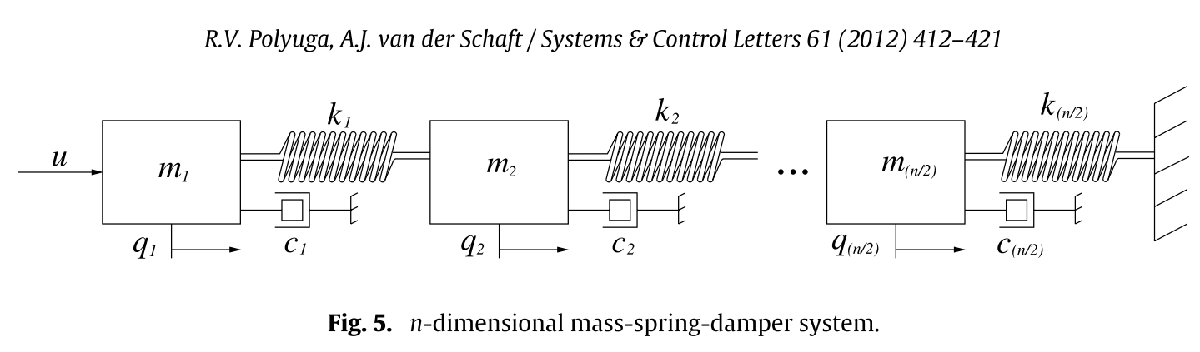

We consider a model with dimension $n = 100$, i.e. 50 masses ($m_i = 4\text{kg}$), 50 springs ($k_i = 4\text{kgs}^{-2}$) and 50 dampers ($c_i=1\text{kgs}^{-1}$).

sys = sss(setup_MassSpringDamperSystem(100,4,4,1,'SISO'))

sys =   (SSS)(SISO)
  100 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


*dszm* in its simplest form is called by providing only the system to reduce and the desired reduced order:

sysr = dszm(sys, 10)

sysr =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11
   x1       -0.25    -0.5416    -0.4334    -0.2527    -0.5816    0.08378      1.805      2.326     -0.599      3.014     -2.423
   x2    -0.01509    -0.1173     0.2587    -0.1343   -0.04945   -0.04539     0.5061     0.4852     0.2784     0.3932     0.2165
   x3     0.03466    -0.3042    -0.2489    0.03308     0.1122   -0.02439   -0.03627   -0.07222     0.1153    -0.2426     0.3997
   x4     0.01521   -0.08522    -0.2363    -0.0511     0.2289     0.1697     0.2096    -0.1211     0.0447    -0.2245    0.04926
   x5    -0.04063    -0.2546    -0.1379     -0.162    -0.3398    -0.0911     0.6638     0.7771     0.1595     0.7124   -0.01393
   x6     0.08277     0.1405     0.1201    0.05021     0.1899    -0.0632    -0.5624    -0.6867     0.2149    -0.8791     0.4918
   x7      -0.025     -0.146    0.07421     -0.137    0.04465     0.0338    -0.2952     

norm(sys - sysr)

ans = 0.0938

isPassive(ss(sysr))

ans = logical
   1


### Options

*dszm* provides some (nested) options. The levels of options are:

- Top level (*dszm*): e.g. define if explicit system is returned

- Second level (*ss2phs, arnoldi*): e.g. pH representation

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code constructs a reduced pH system:

Opts = struct();
Opts.explicit = true; % Explicit ROM
Opts.makePH = true;   % pH ROM
Opts

Opts = struct with fields:
    explicit: 1
      makePH: 1



sysr = dszm(sys,10,Opts)

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @dszm
            info: []
               J: [11×11 double]
               R: [11×11 double]
               Q: [11×11 double]
               G: [11×1 double]
               E: [11×11 double]
               P: [11×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 11
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


norm(ss(sys) - ss(sysr))

ans = 0.0938

isa(sysr,'phsRed')

ans = logical
   1


### Output

*dszm* provides only the reduced system as output. This ssRed/phsRed object contains additional information which makes the creation more transparent:

sysr.method       % Method with which the system was created (should be @dszm)

ans = function_handle with value:
    @dszm


sysr.parameters     % Execution parameters (options)

ans = struct with fields:
          explicit: 1
            makePH: 1
               tol: 1.0000e-12
    checkPassivity: 0
     projectiveMOR: [1×1 struct]
           arnoldi: [1×1 struct]
        samPassive: [1×1 struct]
            ss2phs: [1×1 struct]
             sadpa: [1×1 struct]
     spectralZeros: [2×11 double]


## References

[1] R. Ionutiu, J. Rommes, and A. C. Antoulas. " Passivity-Preserving Model Reduction Using Dominant Spectral-Zero Interpolation." In: IEEE Transactions on Computer-Aided Design of Integrated Circuits and Systems 27.12 (2008), pp. 2250–2263.

[2] A. C. Antoulas. A new result on passivity preserving model reduction. Systems & Control Letters, 54:361–374, 2005.

[3] D.C. Sorensen. Passivity preserving model reduction via interpolation of spectral zeros. In 2003 European Control Conference (ECC), pp. 974–978, 2003.

[4] J. Rommes and N. Martins. “Efficient Computation of Multivariable Transfer Function Dominant Poles Using Subspace Acceleration.” In: IEEE Transactions on Power Systems 21.4 (2006), pp. 1471–1483.

[5] J. Rommes and N. Martins. “Efficient computation of transfer function dominant poles using subspace acceleration.” In: IEEE Transactions on Power Systems 21.3 (2006), pp. 1218–1226.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)